# ACM 11: Week 5 In-class exercise 1

## Steepest Descent Method (first-order)

In this exercise we will explore how the steepest descent method behaves differently when we change the step sizes. Let's consider the same unconstrained optimization problem:


$$\min_{(x,y) \in \mathbb{R}^{2}}\frac{1}{2}(10x^2+y^2)+5\log(1+e^{-x-y})$$


The code block below sets up the objective function and its gradient, then plots the function as a surface and plots the function contours. The true minimum is labeled on the contours.

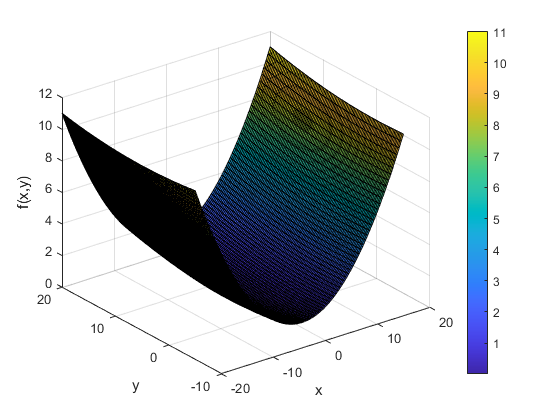

% Set up the optimization problem
% Grid for plots
[x,y] = meshgrid(linspace(-20,20),linspace(-5,20)); 

% Objective function
f = @(x,y) 1/200*((10*x.^2+y.^2)/2+5*log(1+exp(-x-y))); 

% Gradient
df = @(x,y) 1/200*[10*x-5*exp(-x-y)./(1+exp(-x-y)) ; y-5*exp(-x-y)./(1+exp(-x-y)) ];

figure(1); clf
surf(x,y,f(x,y)); colorbar
xlabel('x'); ylabel('y'); zlabel('f(x,y)')

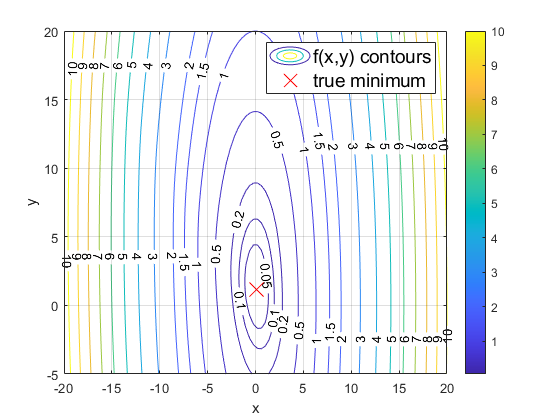


% Contour plot
figure(2); clf;
[c,h] = contour(x,y,f(x,y),[1e-3, 1e-2, 5e-2, 0.1 0.2 0.5 1.5 1 2 3 4 5 6 7 8 9 10]); %contour plot
clabel(c,h)
colorbar
xlabel('x')
ylabel('y')
grid on; hold on
% Label the "exact" solution
a = 0.112467185172334; 
b = 1.124671851723441; 
plot(a,b,'rx','MarkerSize',15); 
legend('f(x,y) contours','true minimum','FontSize',14)

**In-class activity: write your answers below each prompt and upload to Canvas when you are done (one upload per group is fine)**

**(0) Introduce yourselves to each other in the breakout room - name, optional pronouns, year, major and house is good. Please list full names of all students in your group:**

**Kyle McGraw**

**(1) Let's first try using the steepest descent method without a line search. Change the fixed step size **$$\alpha$$** using the drop-down menu and observe how the steepest descent method behaves differently. **

The code block below implements the steepest descent method for you and plots the resulting optimization path. Notice that the step direction is always perpendicular to the contours (you might remember from multivariable calculus that the gradient is perpendicular to the contours).

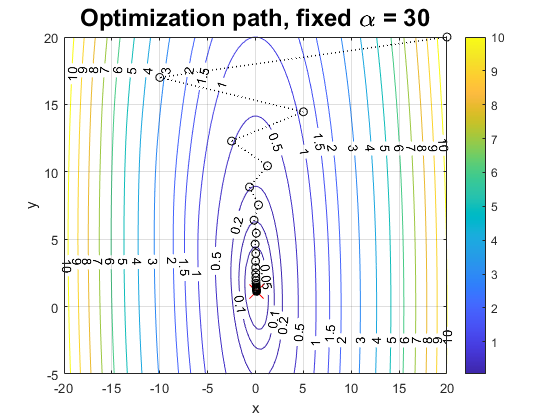

% Initialize plot 
figure(3); clf;
[c,h] = contour(x,y,f(x,y),[1e-3, 1e-2, 5e-2, 0.1 0.2 0.5 1.5 1 2 3 4 5 6 7 8 9 10]); %contour plot
clabel(c,h)
colorbar
xlabel('x')
ylabel('y')
grid on; hold on
% Label the "exact" solution
a = 0.112467185172334; 
b = 1.124671851723441 ; 
plot(a,b,'rx','MarkerSize',15); 

% Set the parameters
xn = 20; % initial x guess
yn = 20; % initial y guess
Nmax = 250; %maximum iterations

iterates_1 = zeros(Nmax,2); % initialize array for storing error
alpha = 30; % varying step size
for i = 1:Nmax
    g = df(xn,yn); % evaluate gradient

    figure(3);
    % Plot the optimization path    
    plot([xn, xn-alpha*g(1)],[yn yn-alpha*g(2);],'k:','LineWidth',1);
    hold on
    plot(xn, yn,'ko')
    xn = xn - alpha*g(1);  % go down the gradient in x direction
    yn = yn - alpha*g(2);  % go down the gradient in y direction 
    iterates_1(i,:) = [xn yn];

    % Convergence check
    if norm(df(xn,yn)) < 1e-6
        break
    end
end
iterates_1 = iterates_1(1:i,:);

xlabel('x')
ylabel('y')
title(['Optimization path, fixed \alpha = ',num2str(alpha)],'FontSize',18)

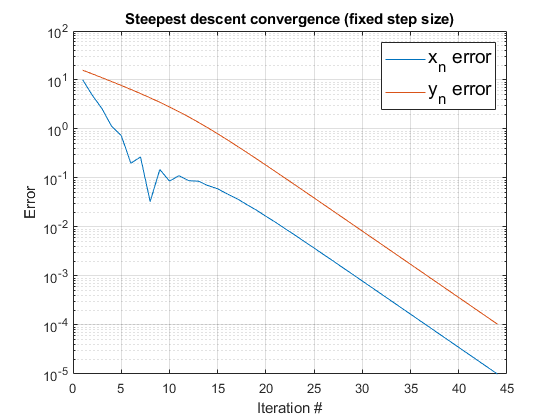


% Plot the decay of the error's absolute value in two directions
figure(4); clf
semilogy(abs(iterates_1(:,1)-a)); hold on 
semilogy(abs(iterates_1(:,2)-b)); grid on
xlabel('Iteration #')
ylabel('Error')
legend('x_n error','y_n error','FontSize',14)
title('Steepest descent convergence (fixed step size)','FontSize',18)
set(gca,'fontsize',10);

**1a: Start with **$\alpha =30$. **How many steps does the gradient descent algorithm take to converge?**

It takes around 45 steps for the algorithm to converge.

**1b: When you take a very small **$\alpha$, **does the gradient descent algorithm converge in the maximum number of allowed iterations? Explain why or why not.**

With small a, it does not converge because the steps are too small to make significant progress.

**1c: When you take a large **$\alpha$, **does the gradient descent algorithm converge in the maximum number of allowed iterations? Explain why or why not.**

WIth large a, it also does not coverge because the steps are too big that they jump past the optimum and get further away on the opposite side.

**1d: For **$\alpha =10,20,30$, **we expect the algorithm to converge. How does the number of iterations required for convergence vary as step size is increased?**

WIth 10, 20, and 30, we have around 150, 70, and 45 steps, respectively. The number of steps decreases as step size increases.

**(2) Line search preview:**

**An alternative to using a fixed step size is to change the step size at each step. The way we set this step size is to minimize the function along the descent direction, and take the step that leads to the minimum cost in that direction. The code below implements this for you. **

**Run the code below, and look at the resulting optimization path. How can you tell from the plot that each step minimizes the cost along the search direction? How many iterations are required to converge?**

**We can tell because it goes along the search direction until it lines up with the optimum so it can't be optimized any more in that direction. Only 5 iterations are required.**

% Contour plot
figure(3); clf;
[c,h] = contour(x,y,f(x,y),[1e-3, 1e-2, 5e-2, 0.1 0.2 0.5 1.5 1 2 3 4 5 6 7 8 9 10]); % contour plot
clabel(c,h)
grid on; hold on

% Set the parameters
xn = 20; % initial x guess
yn = 20; % initial y guess
Nmax = 500; % maximum iterations

% Label the "exact" solution
a = 0.112467185172334; 
b = 1.124671851723441; 
plot(a,b,'rx','MarkerSize',15); 

The code block below performs the steepest descent method with line search, where the bisection method is used to find the optimal step size in each iteration:

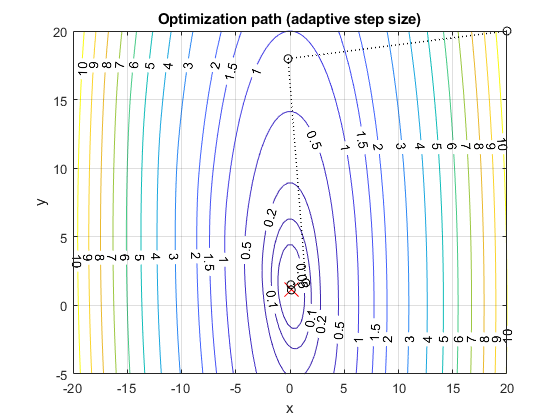

iterates_2= zeros(Nmax,2); % initialize array for storing error
for j = 1:Nmax
    g = df(xn,yn); % evaluate gradient
 
    g = g/norm(g); % normalize gradient direction
    dfv = @(x) df(x(1),x(2))'*g; 
    % dfv is the bisection objective function, directional derivative
    % in g direction
    an = bisection(dfv,[xn; yn],[xn-30*g(1); yn-30*g(2)],1e-10,40); 
    % call bisection function to find best step size, bisection returns
    % what it think is the best place to step next
    figure(3);
    % Plot the optimization path
    plot([xn, an(1,end)],[yn an(2,end)],'k:','LineWidth',1);
    hold on
    plot(xn, yn,'ko')
    xn = an(1,end);  % retrieve x from bisection output
    yn = an(2,end);  % retrieve y from bisection output
    iterates_2(j,:) = [xn yn];

    % convergence check
    if norm(df(xn,yn)) < 1e-6
        break
    end
end
iterates_2 = iterates_2(1:j,:);

xlabel('x')
ylabel('y')
title('Optimization path (adaptive step size)')

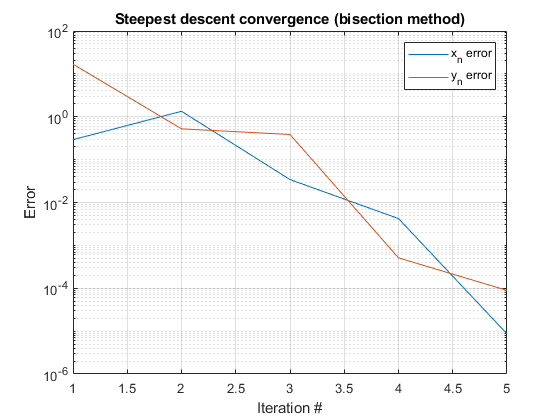


% Plot the decay of the error's absolute value in two directions
a = 0.112467185172334; b = 1.124671851723441 ; 
figure(4); clf; 
semilogy(abs(iterates_2(:,1)-a)); hold on 
semilogy(abs(iterates_2(:,2)-b)); grid on
xlabel('Iteration #')
ylabel('Error')
legend('x_n error','y_n error')
title('Steepest descent convergence (bisection method)')
set(gca,'fontsize',10);

**(3) Comment on what you observed from the plots. When line search is not used, how does the steepest descent method behave differently with respect to different step sizes **$\alpha$**? Does line search improve the efficiency of the steepest descent method?**

**When line search is not used, increasing step size decreases time up until a point where it starts over shooting the optimum. Line search greatly decreases the amount of iterations needed.**